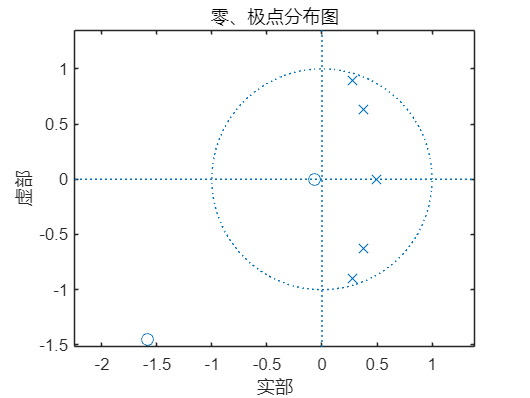

%% 1. 定义系统传递函数的分子和分母系数
% 分子系数 B（对应 z^0 到 z^-5 项）
B = [0.0528, 0.0797, 0.1295, 0.1295, 0.797, 0.0528];  % 分子多项式系数
% 分母系数 A（对应 z^0 到 z^-5 项）
A = [1, -1.8107, 2.4947, -1.8801, 0.9537, -0.2336];    % 分母多项式系数

%% 2. 计算系统的零、极点和增益
% ==============================
[z, p, k] = tf2zp(B, A);   % 调用 tf2zp 函数计算零极点

%% 3. 绘制零、极点分布图
% ========================
figure;
zplane(z, p);               % 绘制零极点图
title('零、极点分布图');
xlabel('实部'); ylabel('虚部');

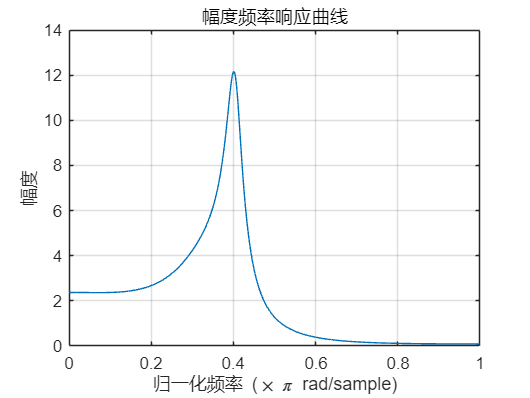


%% 4. 计算频率响应并绘制幅度响应曲线
% ================================
N = 1024;                   % 频率采样点数
[H, w] = freqz(B, A, N);    % 计算频率响应

figure;
plot(w/pi, abs(H));         % 绘制幅度响应（横轴归一化为 0~1）
title('幅度频率响应曲线');
xlabel('归一化频率 (\times \pi rad/sample)');
ylabel('幅度');
grid on;


%% 5. 结果输出
% ============
disp('系统零点：'); disp(z);

系统零点：
  -1.5870 + 1.4470i
  -1.5870 - 1.4470i
   0.8657 + 1.5779i
   0.8657 - 1.5779i
  -0.0669 + 0.0000i



disp('系统极点：'); disp(p);

系统极点：
   0.2788 + 0.8973i
   0.2788 - 0.8973i
   0.3811 + 0.6274i
   0.3811 - 0.6274i
   0.4910 + 0.0000i



disp('系统增益：'); disp(k);

系统增益：
    0.0528

